
load long_modem_rx.mat

% The received signal includes a bunch of samples from before the
% transmission started so we need discard these samples that occurred before
% the transmission started. 

start_idx = find_start_of_signal(y_r,x_sync);

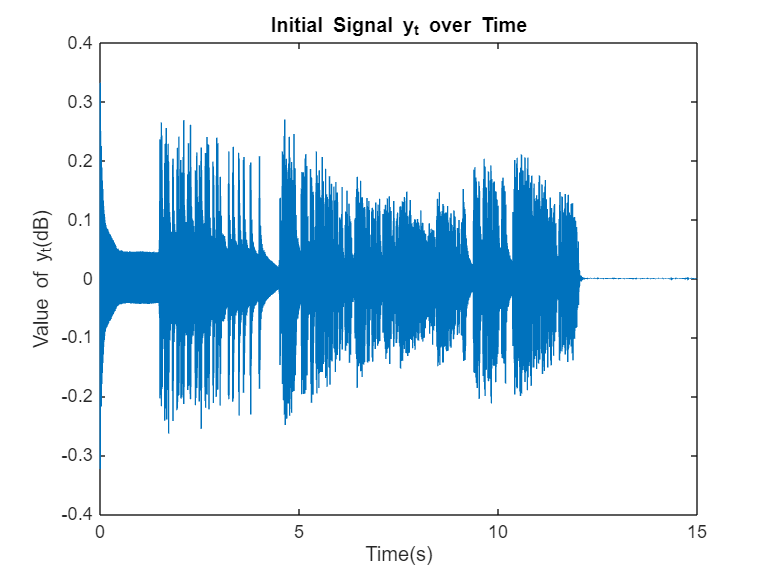

% start_idx now contains the location in y_r where x_sync begins
% we need to offset by the length of x_sync to only include the signal
% we are interested in
y_t = y_r(start_idx+length(x_sync):end); % y_t is the signal which starts at the beginning of the transmission


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%  Put your decoder code here
t = (0:length(y_t)-1)'/Fs; 
plot(t, y_t)
title("Initial Signal y_t over Time")
xlabel("Time(s)")
ylabel("Value of y_t(dB)")

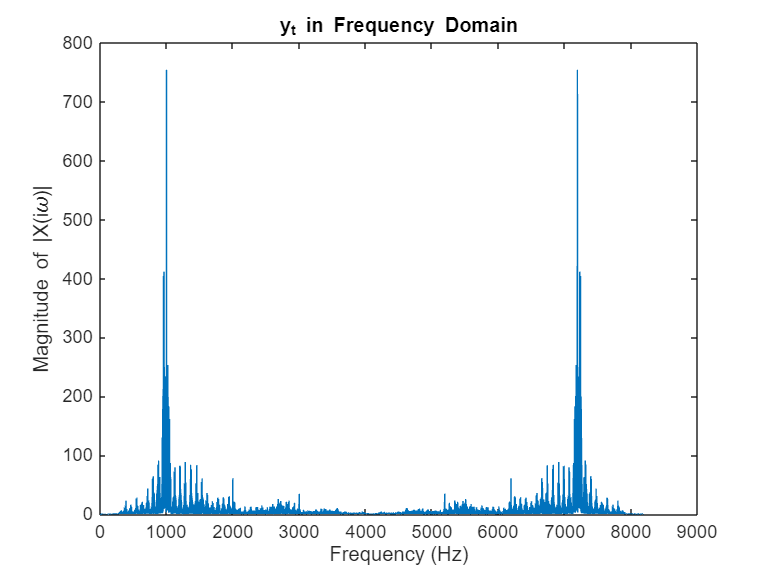

f = 1.0e+03 *

         0    0.0001    0.0001    0.0002    0.0003    0.0003    0.0004    0.0005    0.0005    0.0006    0.0007    0.0007    0.0008    0.0009    0.0009    0.0010    0.0011    0.0011    0.0012    0.0013    0.0013    0.0014    0.0015    0.0015    0.0016    0.0017    0.0017    0.0018    0.0019    0.0019    0.0020    0.0021    0.0021    0.0022    0.0023    0.0023    0.0024    0.0025    0.0025    0.0026    0.0027    0.0027    0.0028    0.0029    0.0029    0.0030    0.0031    0.0031    0.0032    0.0033


X = 1.0e+02 *

   0.0022 + 0.0000i
   0.0015 - 0.0003i
   0.0009 + 0.0003i
   0.0020 - 0.0004i
   0.0015 + 0.0001i
   0.0011 + 0.0001i
   0.0016 - 0.0002i
   0.0013 + 0.0001i
   0.0016 + 0.0004i
   0.0013 - 0.0001i



[f, X] = make_frequency_domain_plot(Fs, y_t, "y_t")

soundsc(y_t, Fs)

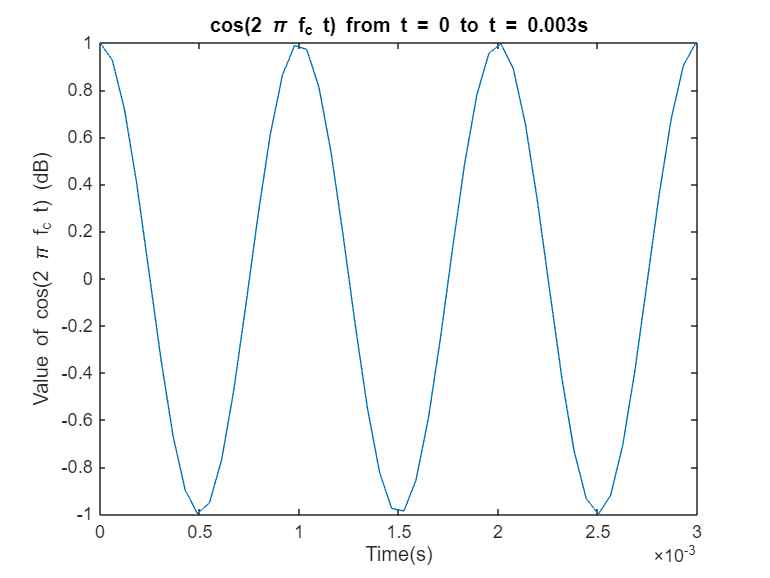


%% 
t_special = (0:length(y_t)-1)'/(Fs*2); 
cosinewave = cos(2*pi*f_c*t);
cosinewave_special = cos(2*pi*f_c*t_special);
plot(t_special(1:50), cosinewave_special(1:50))
title("cos(2 \pi f_c t) from t = 0 to t = 0.003s")
xlabel("Time(s)")
ylabel("Value of cos(2 \pi f_c t) (dB)")

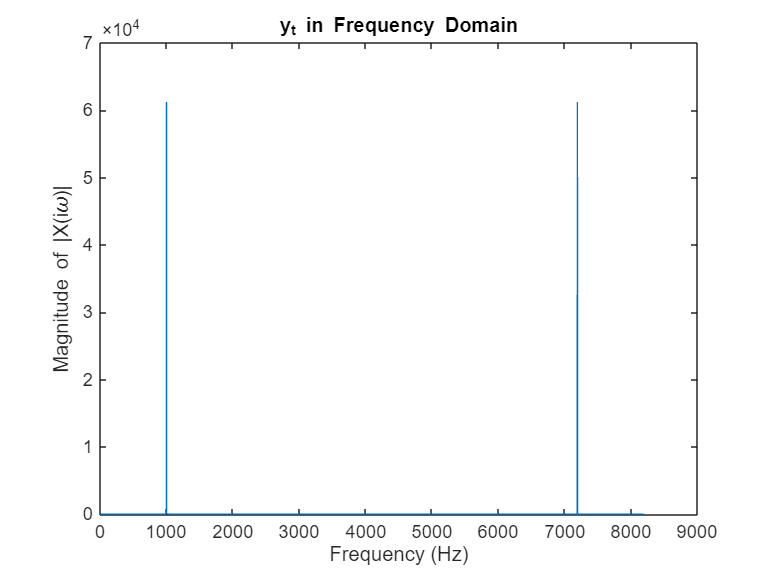

f = 1.0e+03 *

         0    0.0001    0.0001    0.0002    0.0003    0.0003    0.0004    0.0005    0.0005    0.0006    0.0007    0.0007    0.0008    0.0009    0.0009    0.0010    0.0011    0.0011    0.0012    0.0013    0.0013    0.0014    0.0015    0.0015    0.0016    0.0017    0.0017    0.0018    0.0019    0.0019    0.0020    0.0021    0.0021    0.0022    0.0023    0.0023    0.0024    0.0025    0.0025    0.0026    0.0027    0.0027    0.0028    0.0029    0.0029    0.0030    0.0031    0.0031    0.0032    0.0033


X = 1.0e+04 *

   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i




[f, X] = make_frequency_domain_plot(Fs, cosinewave, "y_t")

soundsc(cosinewave, Fs)

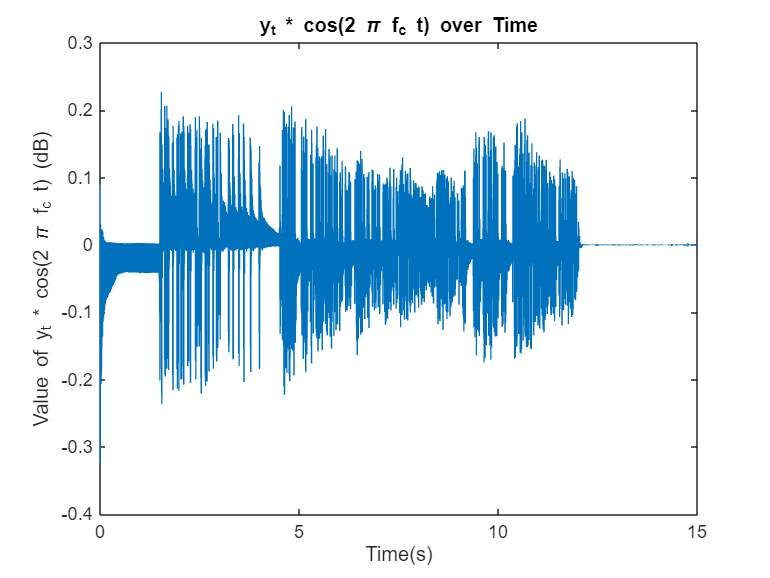

%% 

x_d = y_t .* cosinewave; 
plot(t, x_d)
title("y_t * cos(2 \pi f_c t) over Time")
xlabel("Time(s)")
ylabel("Value of y_t * cos(2 \pi f_c t) (dB)")

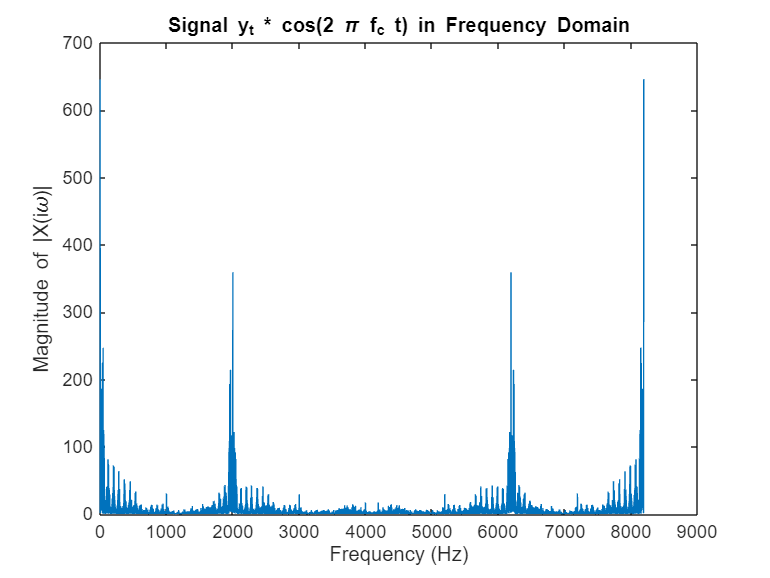

f = 1.0e+03 *

         0    0.0001    0.0001    0.0002    0.0003    0.0003    0.0004    0.0005    0.0005    0.0006    0.0007    0.0007    0.0008    0.0009    0.0009    0.0010    0.0011    0.0011    0.0012    0.0013    0.0013    0.0014    0.0015    0.0015    0.0016    0.0017    0.0017    0.0018    0.0019    0.0019    0.0020    0.0021    0.0021    0.0022    0.0023    0.0023    0.0024    0.0025    0.0025    0.0026    0.0027    0.0027    0.0028    0.0029    0.0029    0.0030    0.0031    0.0031    0.0032    0.0033


X = 1.0e+02 *

  -1.6735 + 0.0000i
   0.0649 - 2.8515i
  -4.6828 - 1.2261i
  -5.3622 + 3.6015i
  -0.0485 + 2.4256i
  -0.7152 + 2.2125i
  -1.3432 + 1.4275i
   1.1675 + 2.3202i
   0.8882 + 0.2677i
  -0.6484 - 0.4730i


[f, X] = make_frequency_domain_plot(Fs, x_d, "Signal y_t * cos(2 \pi f_c t)")

soundsc(x_d, Fs)

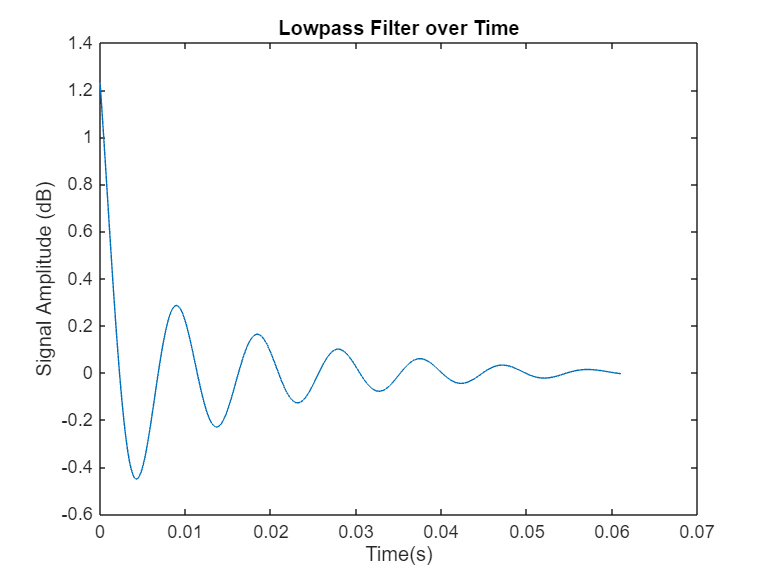

%% 

x_d_fil = lowpass(x_d,100,Fs,'Steepness',0.99);
%% 

lowpass_filter = lowpass([1 ; zeros([500 1])],100,Fs,'Steepness',0.99);
t_sp = (0:length(lowpass_filter)-1)'/Fs;
plot(t_sp, lowpass_filter)
title("Lowpass Filter over Time")
xlabel("Time(s)")
ylabel("Signal Amplitude (dB)")

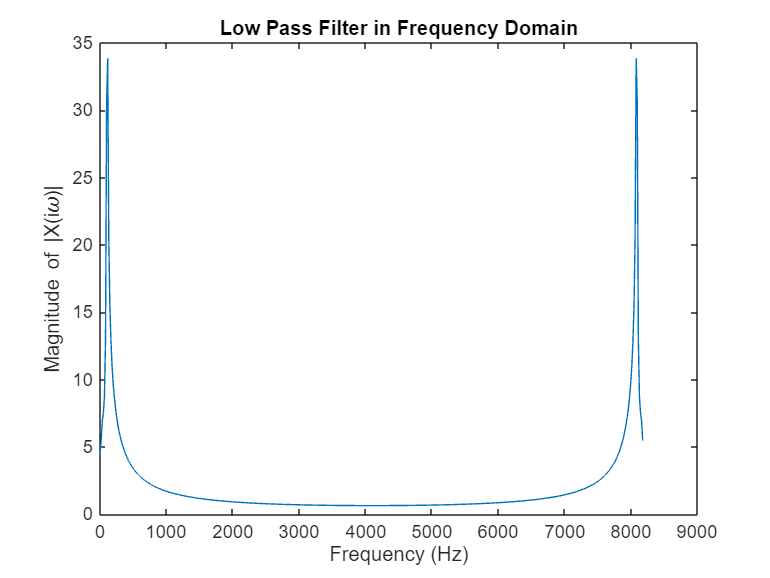

f = 1.0e+03 *

         0    0.0164    0.0327    0.0491    0.0654    0.0818    0.0981    0.1145    0.1308    0.1472    0.1635    0.1799    0.1962    0.2126    0.2289    0.2453    0.2616    0.2780    0.2943    0.3107    0.3270    0.3434    0.3597    0.3761    0.3924    0.4088    0.4251    0.4415    0.4578    0.4742    0.4905    0.5069    0.5232    0.5396    0.5559    0.5723    0.5886    0.6050    0.6213    0.6377    0.6541    0.6704    0.6868    0.7031    0.7195    0.7358    0.7522    0.7685    0.7849    0.8012


X =    4.4670 + 0.0000i
   5.1561 + 1.8288i
   6.4155 + 2.5888i
   6.8853 + 2.9889i
   7.2420 + 4.8816i
   9.6503 + 8.6627i
  24.3339 +18.5341i
  28.9283 -17.6036i
  12.9511 -15.9166i
   8.3505 -13.0928i





[f, X] = make_frequency_domain_plot(Fs, lowpass_filter, "Low Pass Filter")

soundsc(x_d_fil, Fs)

%% 
t_special2 = (1:1:length(x_d_fil))/Fs

t_special2 =     0.0001    0.0002    0.0004    0.0005    0.0006    0.0007    0.0009    0.0010    0.0011    0.0012    0.0013    0.0015    0.0016    0.0017    0.0018    0.0020    0.0021    0.0022    0.0023    0.0024    0.0026    0.0027    0.0028    0.0029    0.0031    0.0032    0.0033    0.0034    0.0035    0.0037    0.0038    0.0039    0.0040    0.0042    0.0043    0.0044    0.0045    0.0046    0.0048    0.0049    0.0050    0.0051    0.0052    0.0054    0.0055    0.0056    0.0057    0.0059    0.0060    0.0061


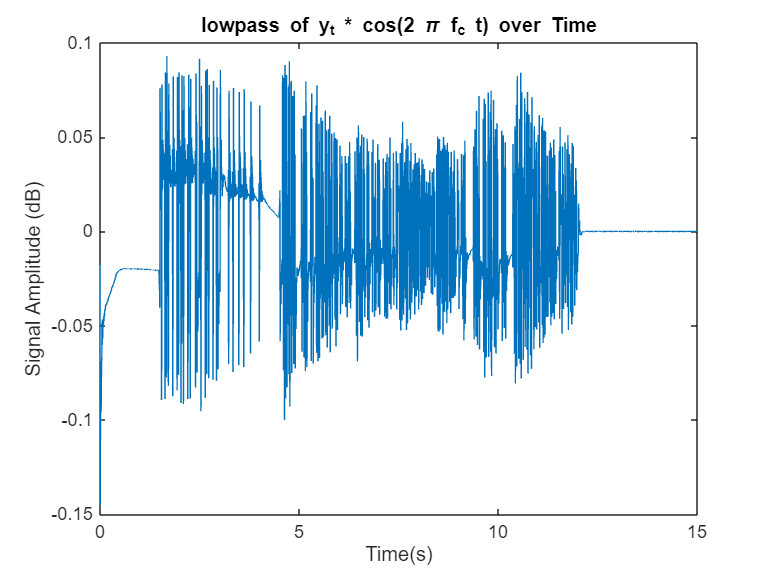

plot(t_special2, x_d_fil)
title("lowpass of y_t * cos(2 \pi f_c t) over Time")
xlabel("Time(s)")
ylabel("Signal Amplitude (dB)")

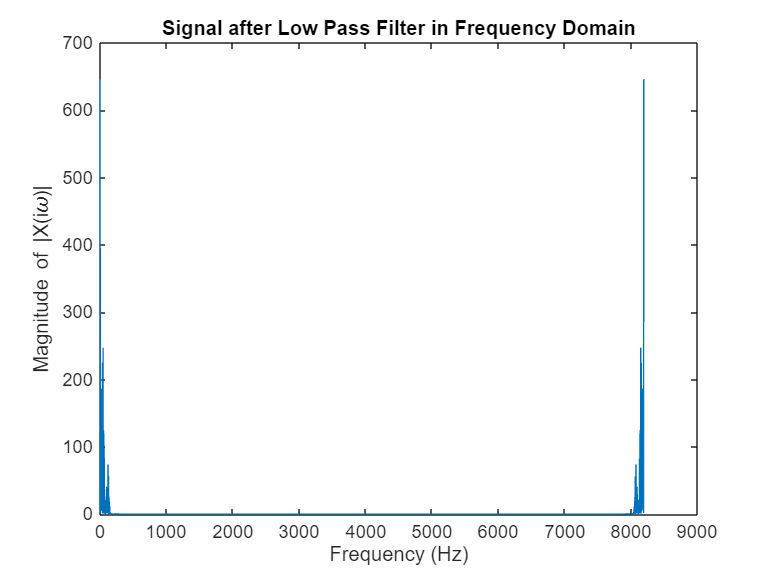

f = 1.0e+03 *

         0    0.0001    0.0001    0.0002    0.0003    0.0003    0.0004    0.0005    0.0005    0.0006    0.0007    0.0007    0.0008    0.0009    0.0009    0.0010    0.0011    0.0011    0.0012    0.0013    0.0013    0.0014    0.0015    0.0015    0.0016    0.0017    0.0017    0.0018    0.0019    0.0019    0.0020    0.0021    0.0021    0.0022    0.0023    0.0023    0.0024    0.0025    0.0025    0.0026    0.0027    0.0027    0.0028    0.0029    0.0029    0.0030    0.0031    0.0031    0.0032    0.0033


X = 1.0e+02 *

  -1.6753 + 0.0000i
   0.0631 - 2.8515i
  -4.6846 - 1.2261i
  -5.3640 + 3.6015i
  -0.0502 + 2.4256i
  -0.7170 + 2.2125i
  -1.3449 + 1.4275i
   1.1658 + 2.3202i
   0.8864 + 0.2677i
  -0.6502 - 0.4730i




[f, X] = make_frequency_domain_plot(Fs, x_d_fil, "Signal after Low Pass Filter")

soundsc(x_d_fil, Fs)


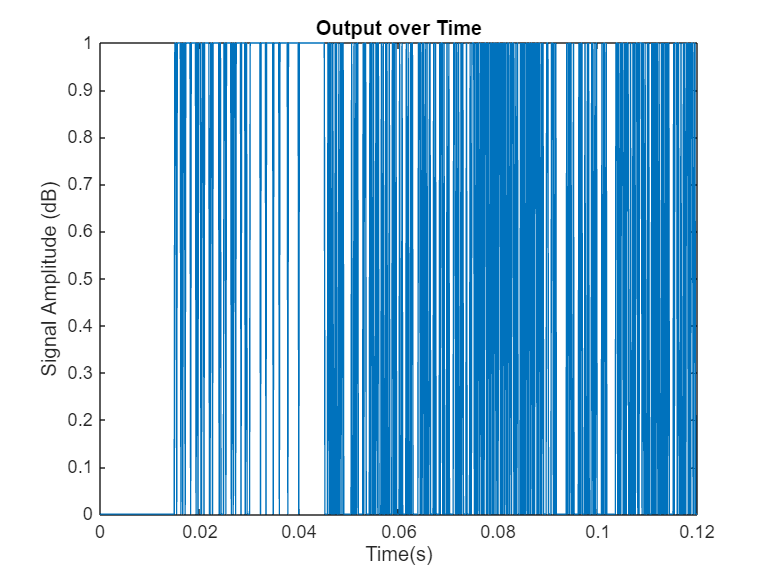

per = 100; 

mid_idx = (per/2):per:length(x_d_fil); % middle of each bit
s_vals = x_d_fil(mid_idx); % sampled values/bit
d_bit = s_vals > 0; % pos is 1 neg is 0

tot_bits = msg_length*8; % total bits

x_d = d_bit(1:tot_bits); % cut off extra bits at the end
t = (0:length(x_d)-1)'/Fs;
plot(t, x_d)
title("Output over Time")
xlabel("Time(s)")
ylabel("Signal Amplitude (dB)")

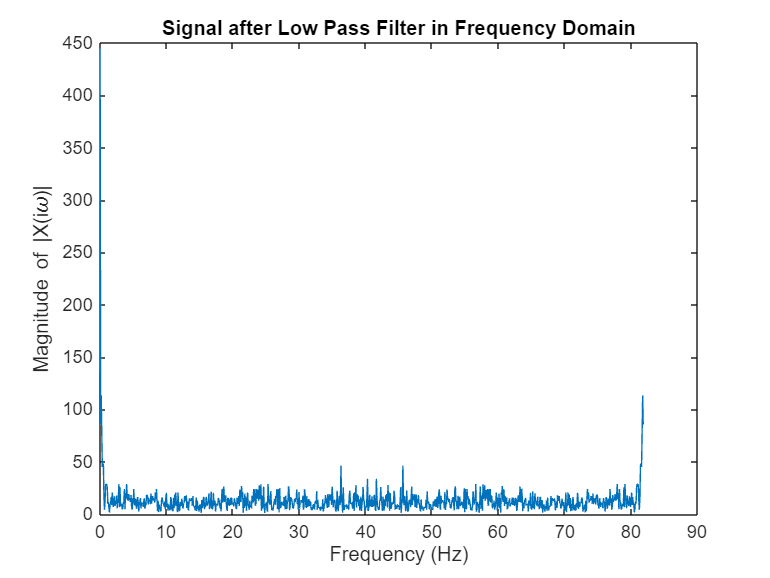

f =          0    0.0833    0.1665    0.2498    0.3330    0.4163    0.4995    0.5828    0.6660    0.7493    0.8325    0.9158    0.9990    1.0823    1.1655    1.2488    1.3320    1.4153    1.4985    1.5818    1.6650    1.7483    1.8315    1.9148    1.9980    2.0813    2.1646    2.2478    2.3311    2.4143    2.4976    2.5808    2.6641    2.7473    2.8306    2.9138    2.9971    3.0803    3.1636    3.2468    3.3301    3.4133    3.4966    3.5798    3.6631    3.7463    3.8296    3.9128    3.9961    4.0793


X = 1.0e+02 *

   4.4500 + 0.0000i
  -0.3930 - 0.7593i
  -1.0993 + 0.2699i
   0.3194 + 0.7205i
  -0.1496 + 0.4240i
  -0.2044 + 0.4408i
   0.4589 + 0.0916i
   0.0532 - 0.1437i
   0.0413 - 0.0074i
   0.0295 - 0.1298i



[f, X] = make_frequency_domain_plot(Fs/100, x_d, "Signal after Low Pass Filter")

%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

soundsc(x_d*1.00, Fs)
% convert to a string assuming that x_d is a vector of 1s and 0s
% representing the decoded bits.
BitsToString(x_d)

ans = 'The answer to the Ultimate Question of Life, the Universe, and Everything is 42. The question to the ultimate answer is ...'


function [f, X] = make_frequency_domain_plot(Fs, x, Algorithm)
    N = length(x);
    t = (1:1:N)/Fs;
    X = fft(x);
    f = (0:N-1)*(Fs/N);
    plot(f, abs(X))
    xlabel('Frequency (Hz)')
    ylabel('Magnitude of |X(i\omega)|')
    title(Algorithm + ' in Frequency Domain')
end